## Part 1: Radon Transform

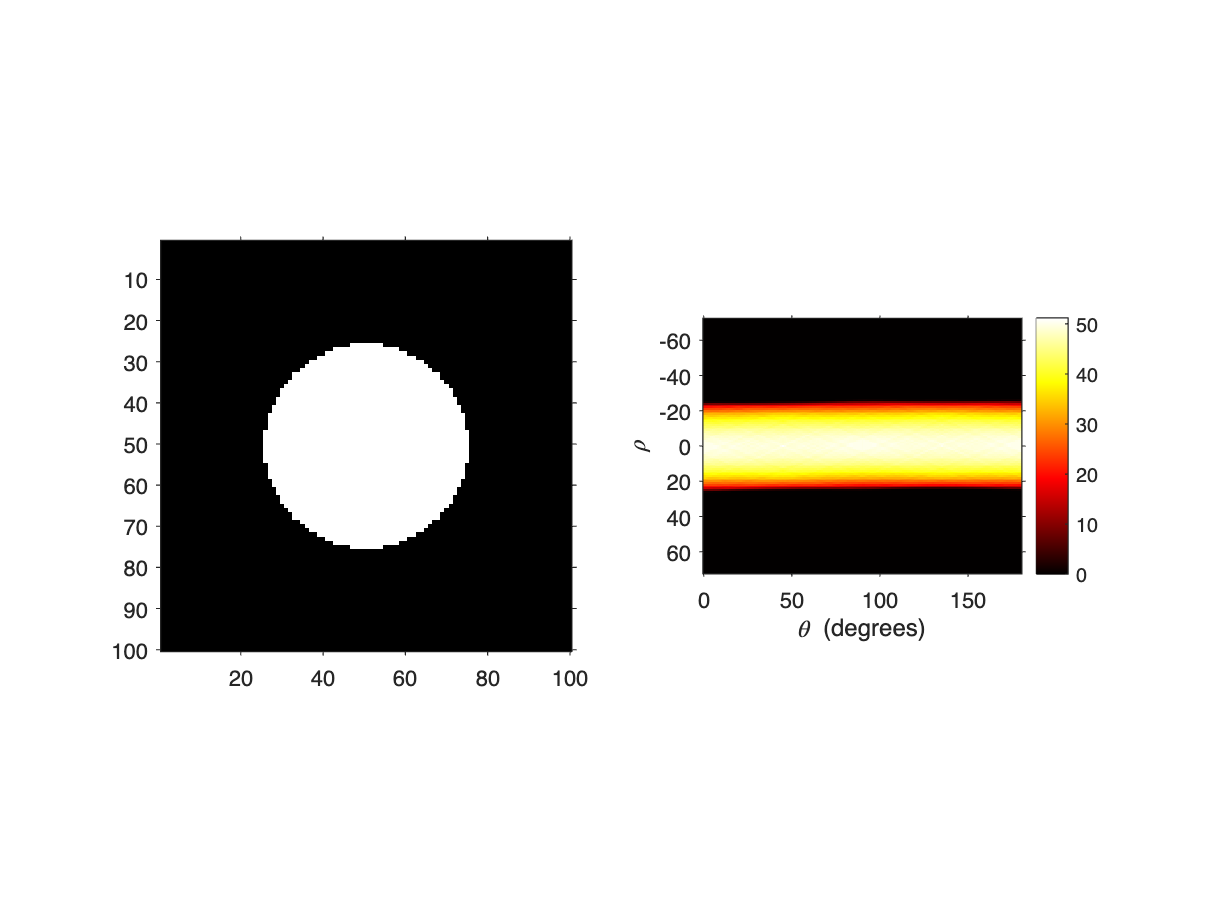

clear all; close all;
x = linspace(-1,1, 100); y = x;
[X,Y] = meshgrid(x,y);
R = sqrt(X.^2 + Y.^2);
C = zeros(size(X));
C = R < 0.5;
figure (1);
subplot(1,2,1);
imshow(C);

theta = 0:180;
[R,p] = radon(C,theta);
subplot(1,2,2);
iptsetpref('ImshowAxesVisible','on')
imshow(R,[],'Xdata',theta,'Ydata',p,'InitialMagnification','fit')
xlabel('\theta (degrees)')
ylabel('\rho')
colormap(gca,hot), colorbar

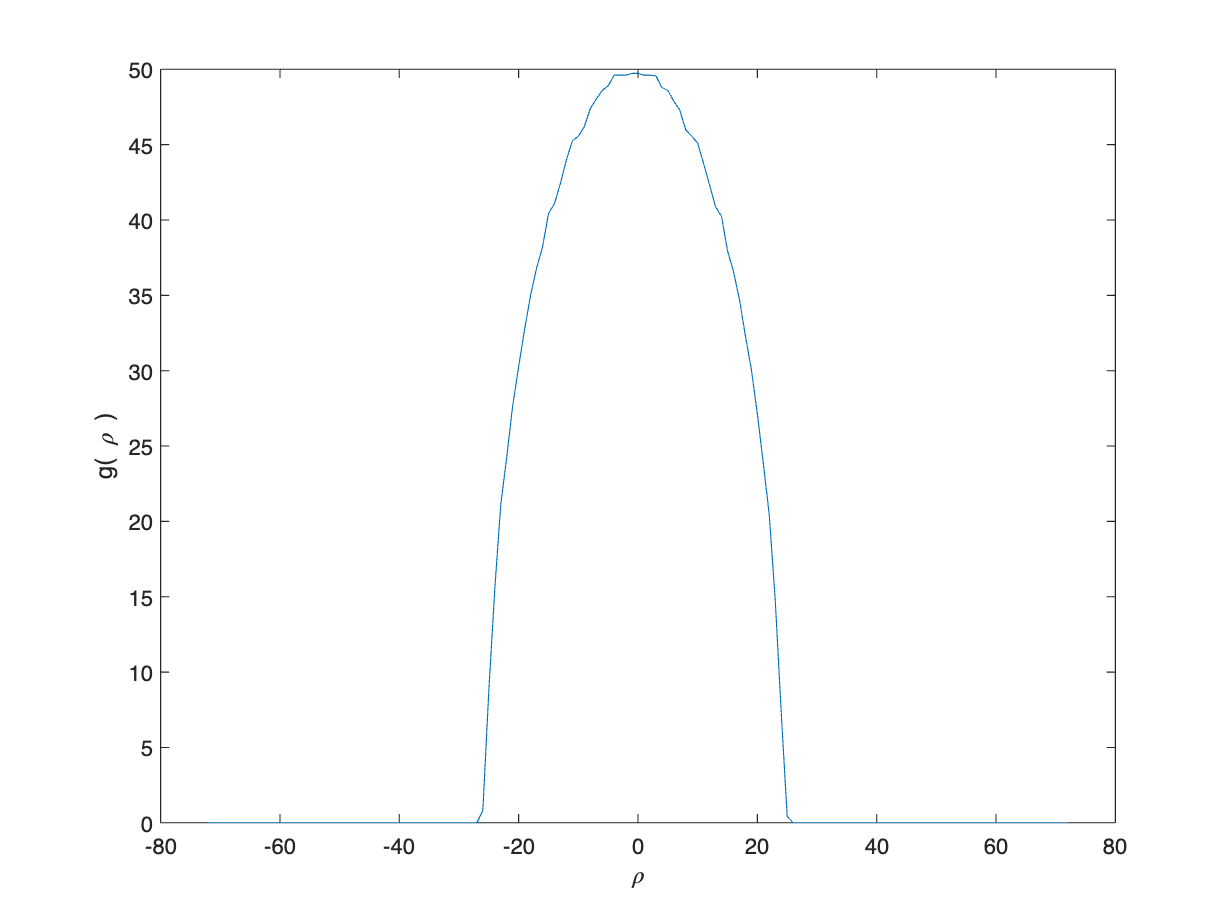


figure();
plot(p,R(:,100));xlabel('\rho');ylabel('g( \rho )');

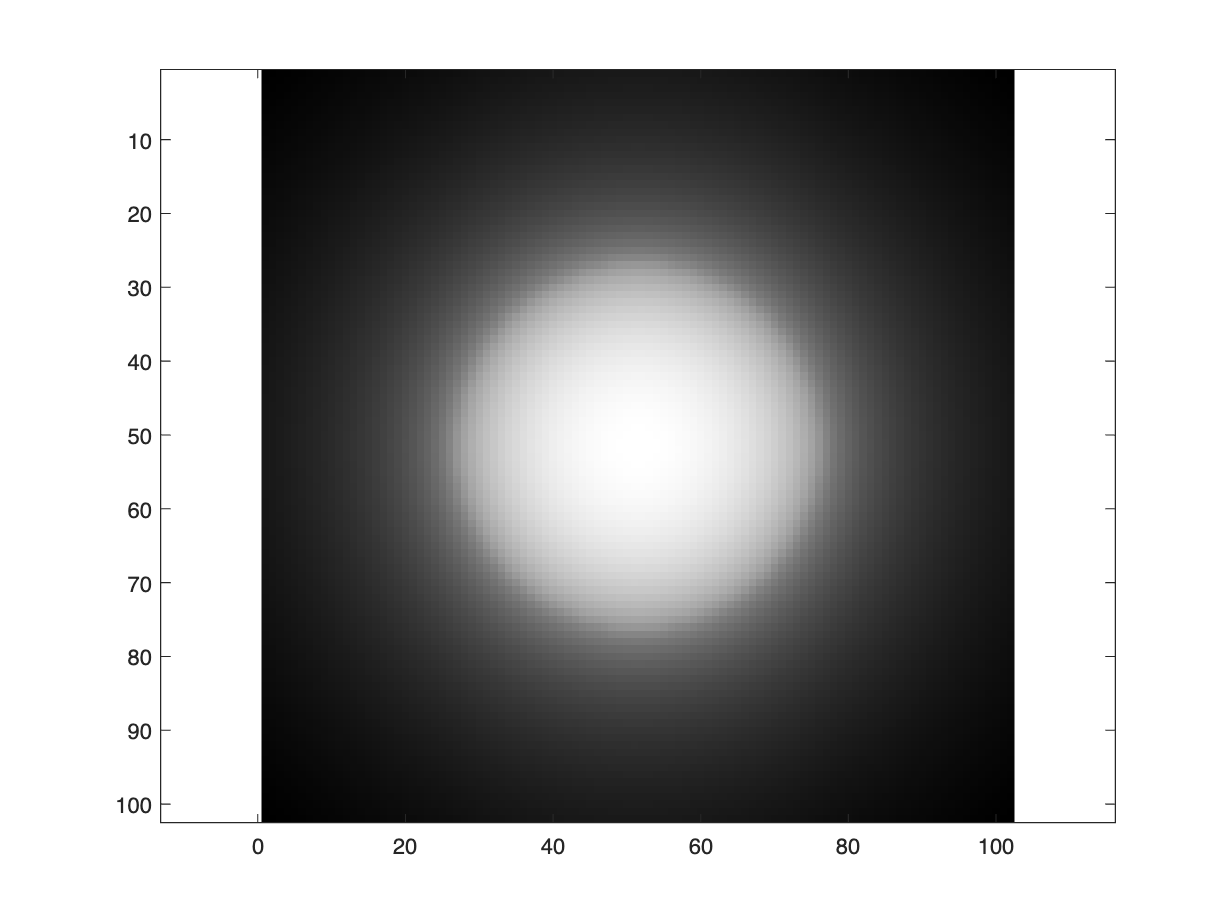


Cp = iradon(R,theta,"linear","None");
%A = imresize(A,[256 256]);
figure();
imagesc(Cp); colormap("gray"); axis equal

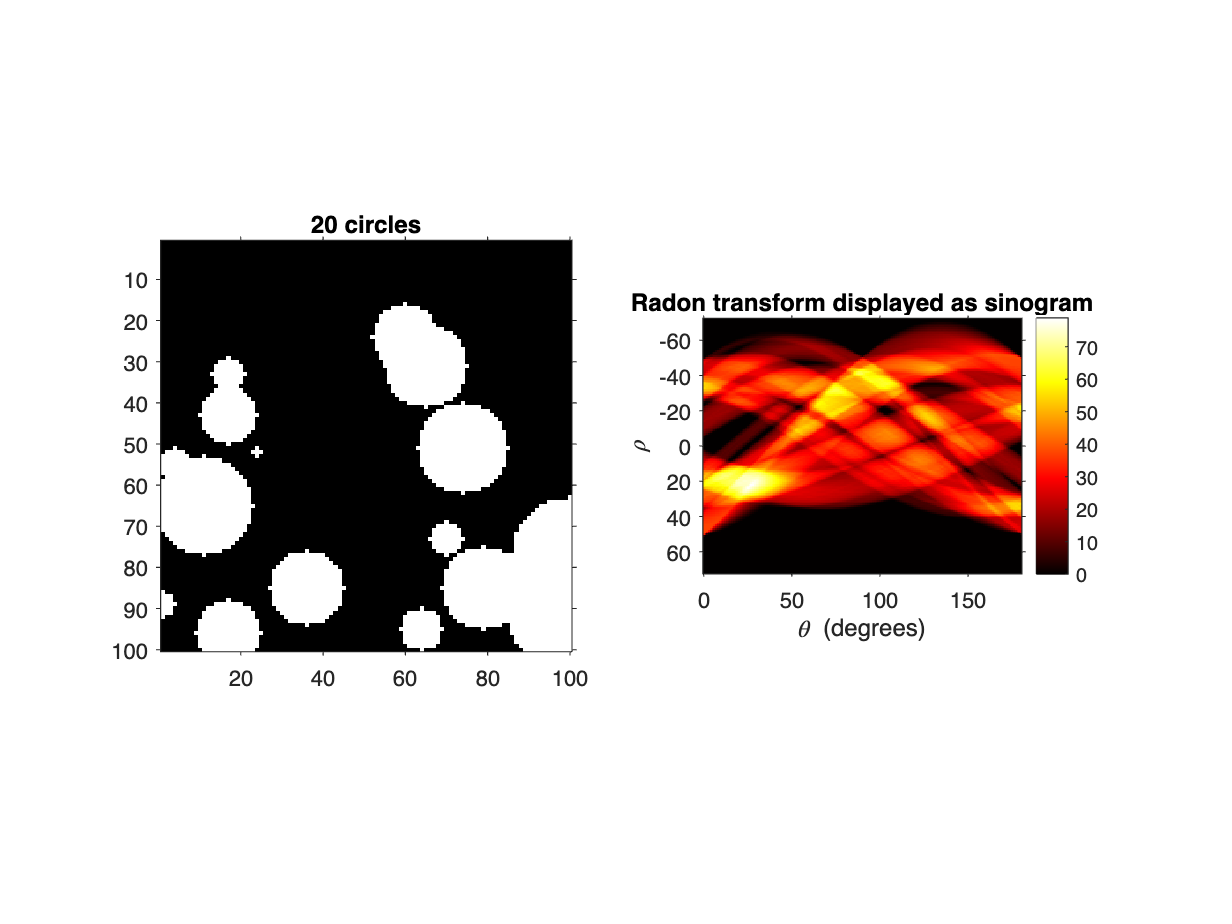

clear all; close all;
% Parameters
imageSize = [100, 100];  % Size of the binary image
numCircles = 20;         % Number of circles to generate
minRadius = 1;          % Minimum radius of circles
maxRadius = 15;          % Maximum radius of circles

% Initialize binary image
binaryImage = false(imageSize);

% Generate random circles
for i = 1:numCircles
    % Generate random center coordinates
    centerX = randi(imageSize(2));
    centerY = randi(imageSize(1));
    
    % Generate random radius
    radius = randi([minRadius, maxRadius]);
    
    % Generate circle
    [columnsInImage, rowsInImage] = meshgrid(1:imageSize(2), 1:imageSize(1));
    circlePixels = (rowsInImage - centerY).^2 + (columnsInImage - centerX).^2 <= radius.^2;
    
    % Add circle to binary image
    binaryImage = binaryImage | circlePixels;
end

% Display binary image
%imshow(binaryImage);
C = binaryImage;
figure ();
subplot(1,2,1);
imshow(C);
title([num2str(numCircles),' circles'])

theta = 0:180;
[R,p] = radon(C,theta);
subplot(1,2,2);
iptsetpref('ImshowAxesVisible','on')
imshow(R,[],'Xdata',theta,'Ydata',p,'InitialMagnification','fit')
xlabel('\theta (degrees)')
ylabel('\rho')
title('Radon transform displayed as sinogram')
colormap(gca,hot), colorbar

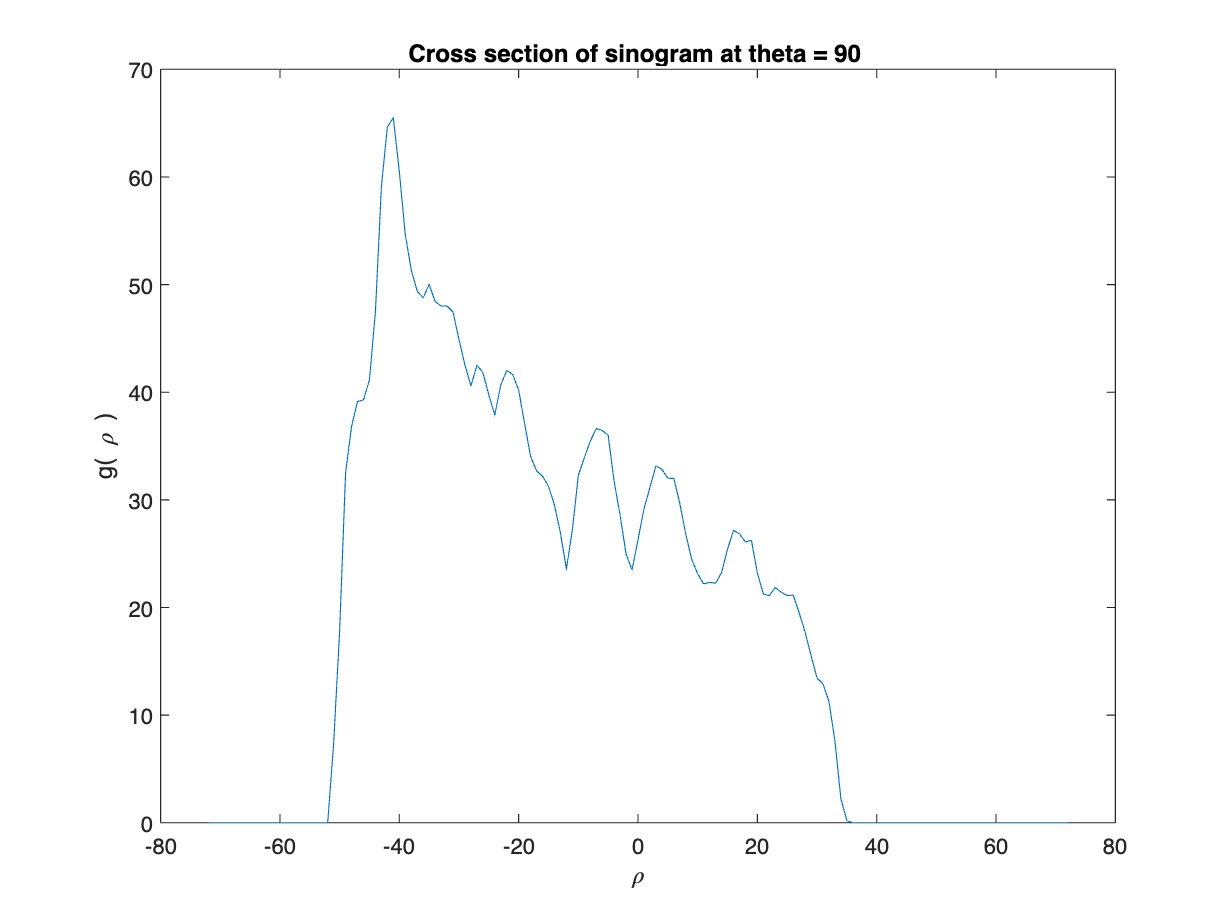

figure()

plot(p,R(:,90));xlabel('\rho');ylabel('g( \rho )');
title('Cross section of sinogram at theta = 90 ')

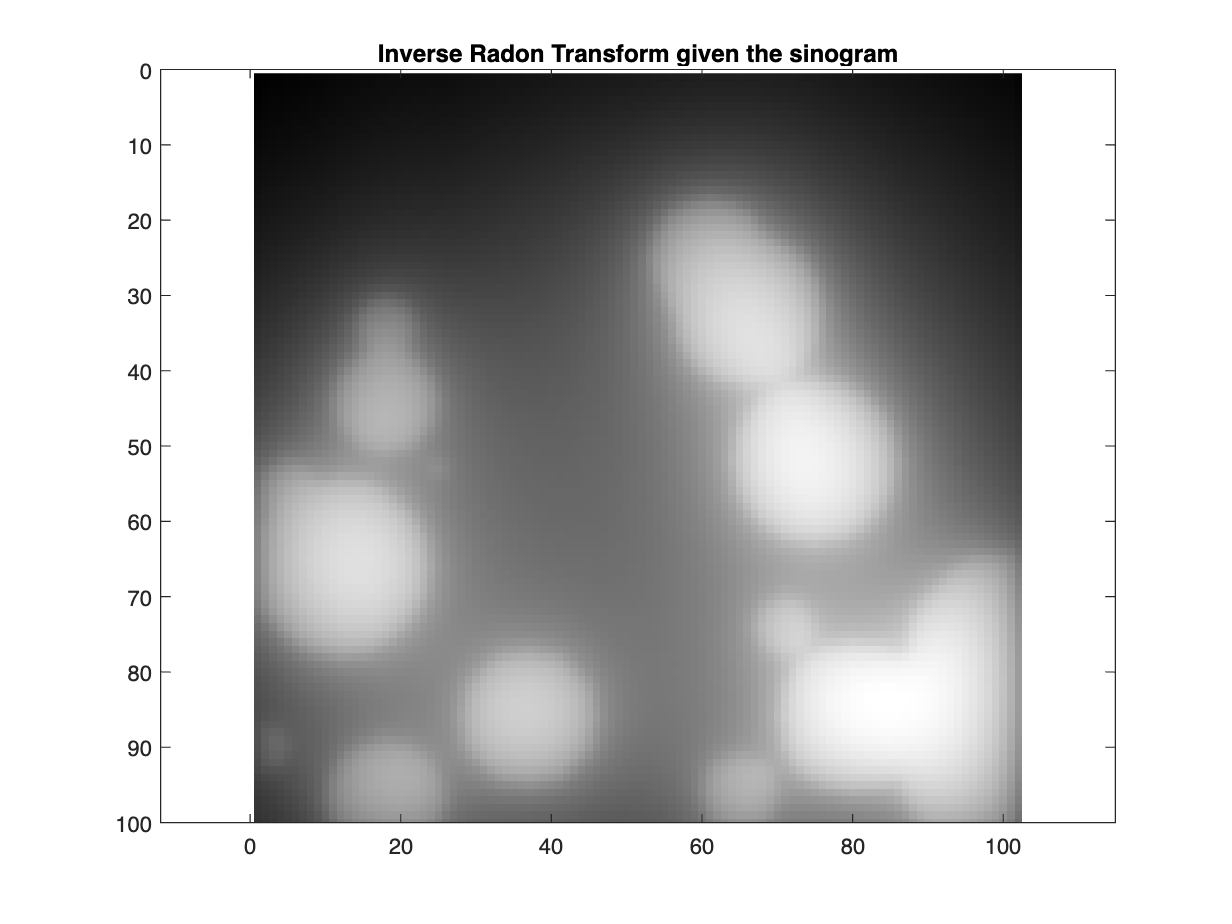



Cp = iradon(R,theta,"linear","None");
%A = imresize(A,[256 256]);

figure()
imagesc(Cp); colormap("gray"); axis equal
ylim([0 100])
 title('Inverse Radon Transform given the sinogram')

**NIP Letters**

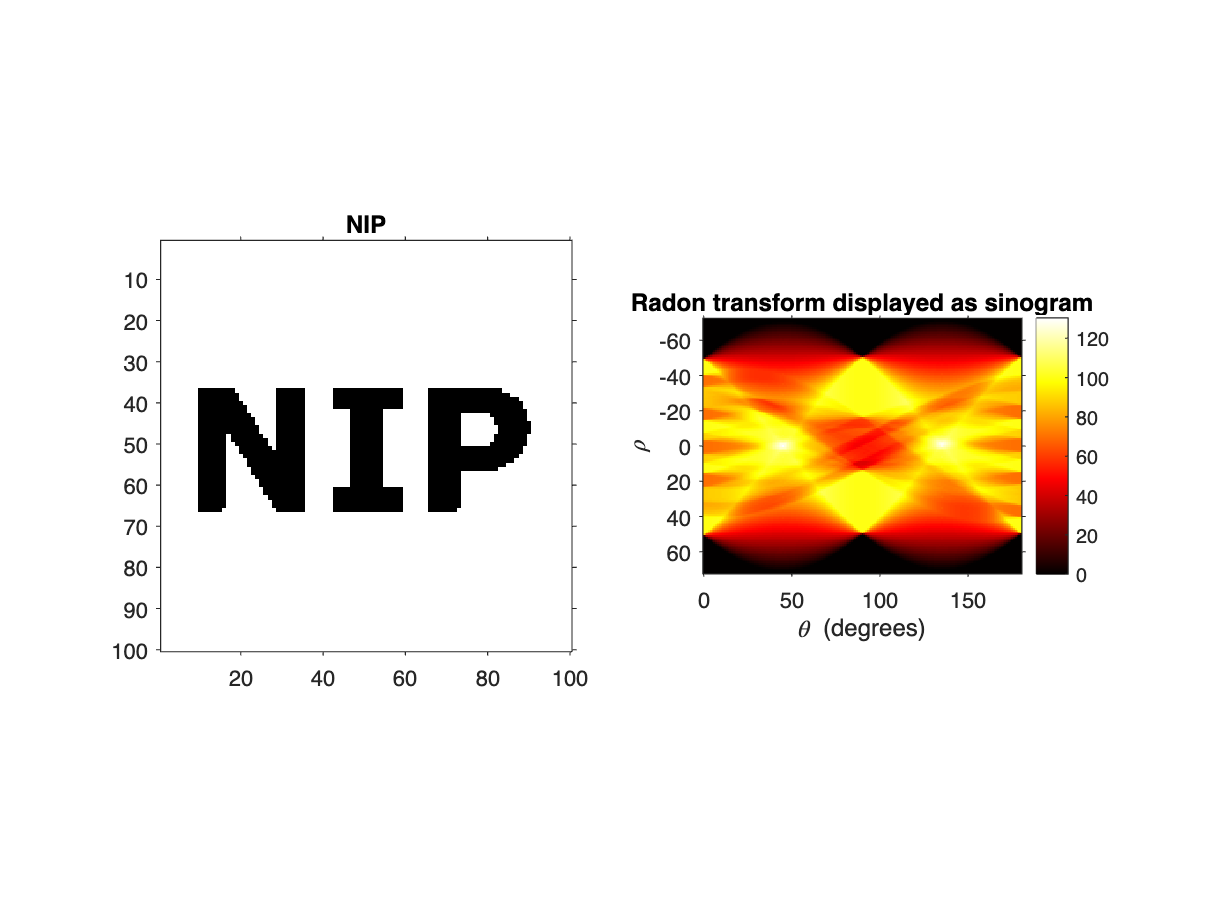

clear all; close all;
I = imread('NIP white.png');
I = imresize(I,[100 100]);
I = im2gray(I);
C = im2bw(I,0.5);


% Display binary image
%imshow(binaryImage);
figure ();
subplot(1,2,1);
imshow(C);
title('NIP')

theta = 0:180;
[R,p] = radon(C,theta);
subplot(1,2,2);
iptsetpref('ImshowAxesVisible','on')
imshow(R,[],'Xdata',theta,'Ydata',p,'InitialMagnification','fit')
xlabel('\theta (degrees)')
ylabel('\rho')
title('Radon transform displayed as sinogram')
colormap(gca,hot), colorbar

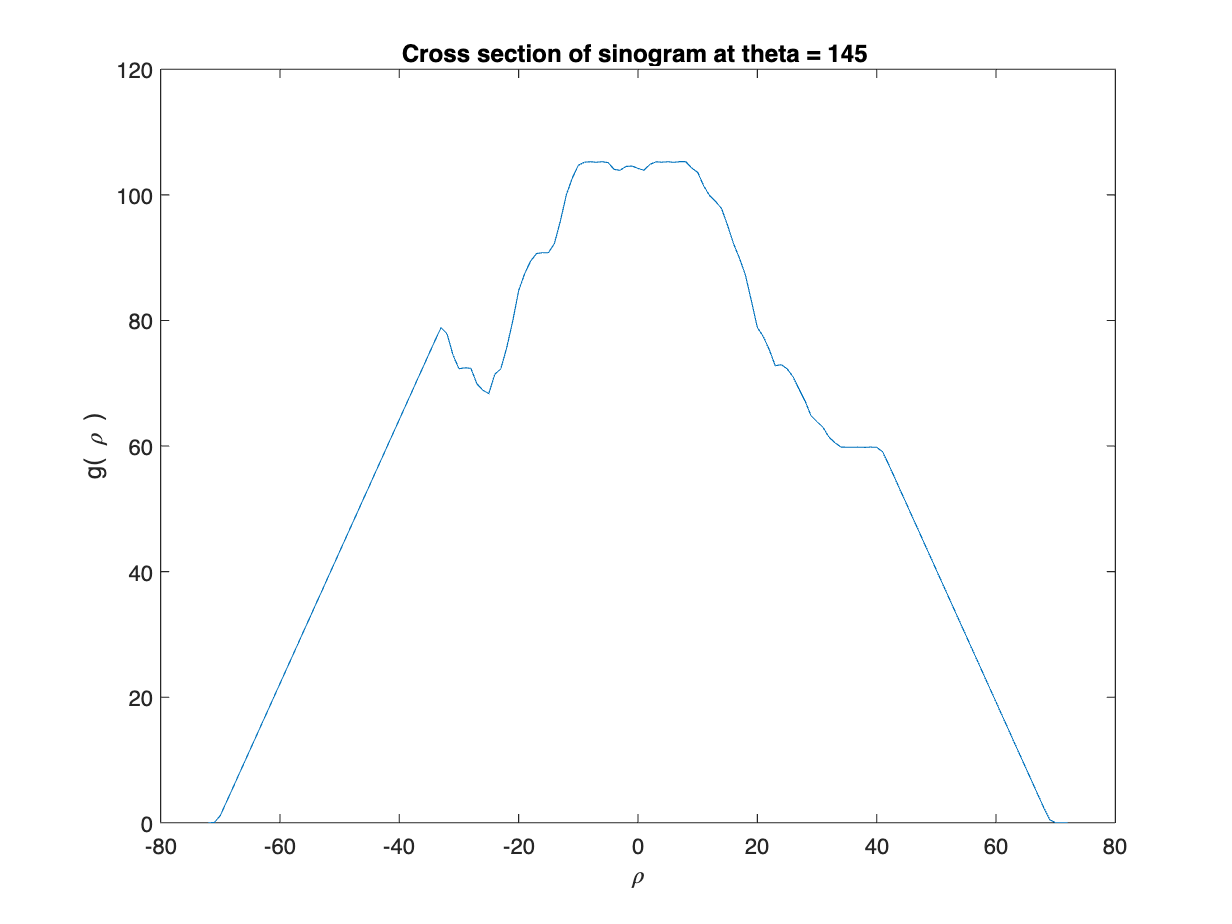

figure()

plot(p,R(:,145));xlabel('\rho');ylabel('g( \rho )');
title('Cross section of sinogram at theta = 145 ')

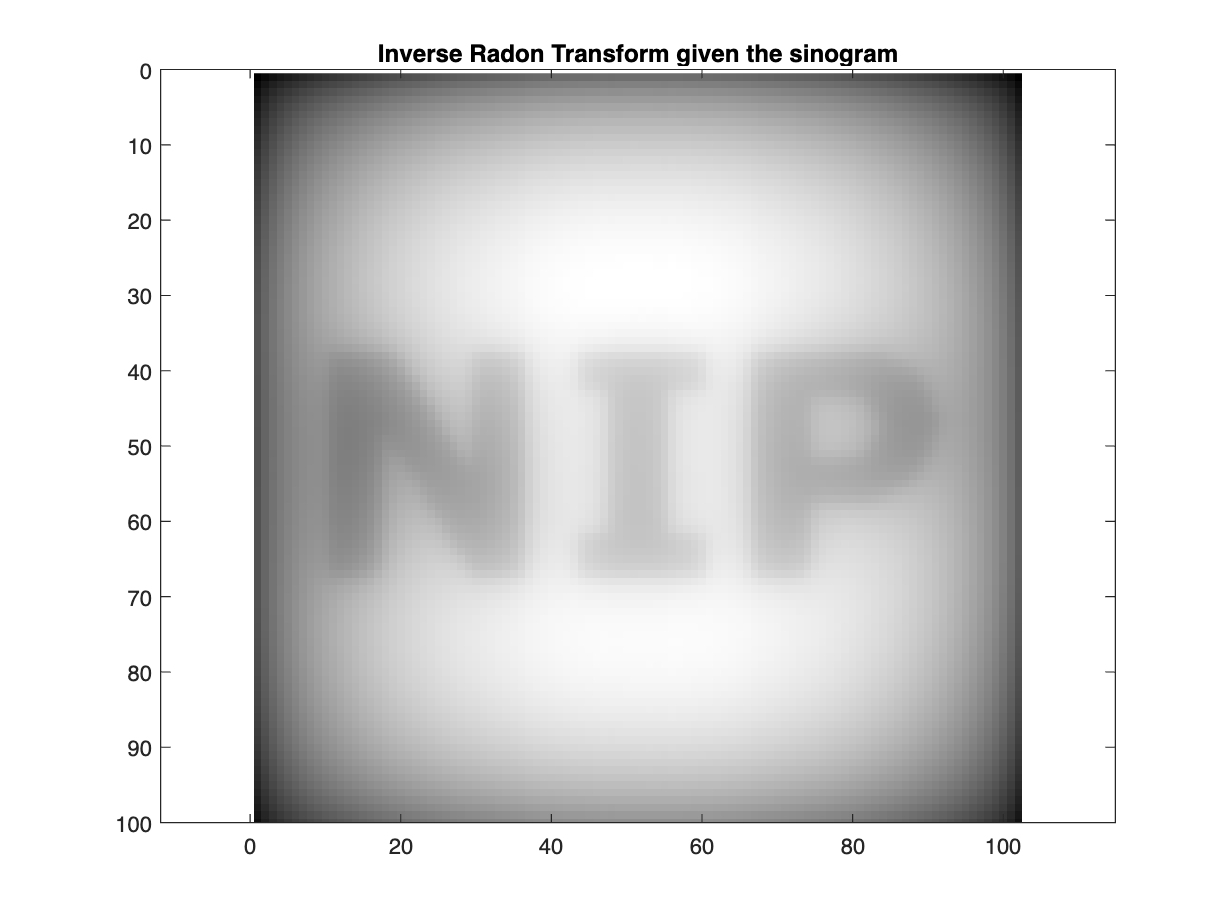



Cp = iradon(R,theta,"linear","None");
%A = imresize(A,[256 256]);

figure()
imagesc(Cp); colormap("gray"); axis equal
ylim([0 100])
 title('Inverse Radon Transform given the sinogram')

## Different filters - fourier slice theorem

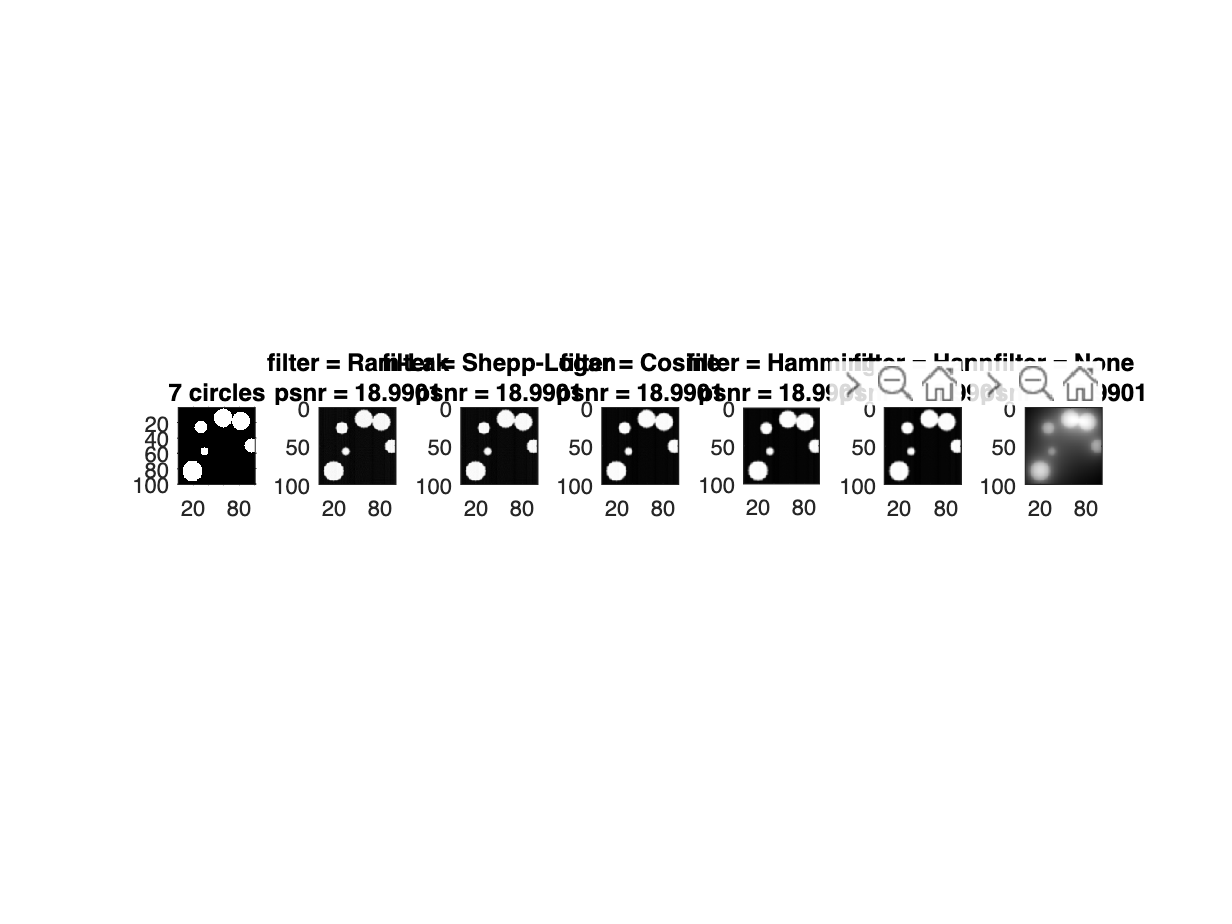

clear all; close all;
imageSize = [100, 100];  % Size of the binary image
numCircles = 7;         % Number of circles to generate
minRadius = 1;          % Minimum radius of circles
maxRadius = 15;          % Maximum radius of circles

binaryImage = false(imageSize);

for i = 1:numCircles
    centerX = randi(imageSize(2));
    centerY = randi(imageSize(1));
    radius = randi([minRadius, maxRadius]);
    [columnsInImage, rowsInImage] = meshgrid(1:imageSize(2), 1:imageSize(1));
    circlePixels = (rowsInImage - centerY).^2 + (columnsInImage - centerX).^2 <= radius.^2;
    binaryImage = binaryImage | circlePixels;
end

% Display binary image
C = binaryImage;

theta = 0:180;
[R,p] = radon(C,theta);

%% Recover image

figure();

subplot(171); 
imshow(C); title([num2str(numCircles),' circles'])

subplot(172); 
Cp = iradon(R,theta,"linear","Ram-Lak");
Cp = imresize(Cp,[100 100]);
psnr_ =psnr(Cp,double(C));
imagesc(Cp); colormap("gray"); 
title({['filter = Ram-Lak'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(173); 
Cp = iradon(R,theta,"linear","Shepp-Logan");
Cp = imresize(Cp,[100 100]);
imagesc(Cp); colormap("gray"); 
title({['filter = Shepp-Logan'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(174); 
Cp = iradon(R,theta,"linear","Cosine");
Cp = imresize(Cp,[100 100]);
imagesc(Cp); colormap("gray"); 
title({['filter = Cosine'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(175); 
Cp = iradon(R,theta,"linear","Hamming");
Cp = imresize(Cp,[100 100]);
imagesc(Cp); colormap("gray"); 
title({['filter = Hamming'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(176); 
Cp = iradon(R,theta,"linear","Hann");
Cp = imresize(Cp,[100 100]);
imagesc(Cp); colormap("gray"); 
title({['filter = Hann'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(177); 
Cp = iradon(R,theta,"linear","None");
Cp = imresize(Cp,[100 100]);
imagesc(Cp); colormap("gray"); 
title({['filter = None'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

## Different filters - fourier slice theorem [NIP]

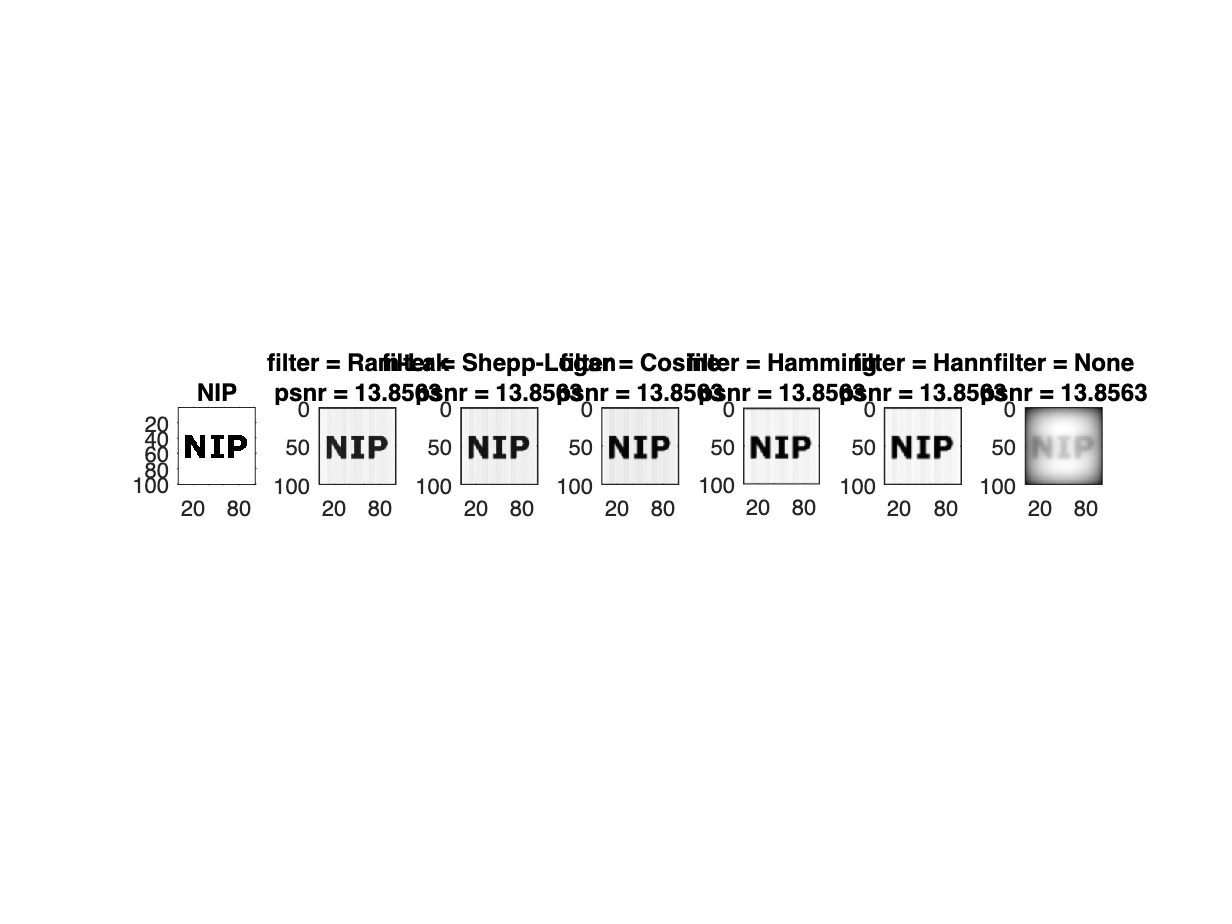

clear all; close all;
I = imread('NIP white.png');
I = imresize(I,[100 100]);
I = im2gray(I);
C = im2bw(I,0.5);

theta = 0:180;
[R,p] = radon(C,theta);

%% Recover image

figure();

subplot(171); 
imshow(C); title('NIP')

subplot(172); 
Cp = iradon(R,theta,"linear","Ram-Lak");
Cp = imresize(Cp,[100 100]);
psnr_ =psnr(Cp,double(C));
imagesc(Cp); colormap("gray"); 
title({['filter = Ram-Lak'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(173); 
Cp = iradon(R,theta,"linear","Shepp-Logan");
Cp = imresize(Cp,[100 100]);
imagesc(Cp); colormap("gray"); 
title({['filter = Shepp-Logan'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(174); 
Cp = iradon(R,theta,"linear","Cosine");
Cp = imresize(Cp,[100 100]);
imagesc(Cp); colormap("gray"); 
title({['filter = Cosine'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(175); 
Cp = iradon(R,theta,"linear","Hamming");
Cp = imresize(Cp,[100 100]);
imagesc(Cp); colormap("gray"); 
title({['filter = Hamming'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(176); 
Cp = iradon(R,theta,"linear","Hann");
Cp = imresize(Cp,[100 100]);
imagesc(Cp); colormap("gray"); 
title({['filter = Hann'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);

subplot(177); 
Cp = iradon(R,theta,"linear","None");
Cp = imresize(Cp,[100 100]);
imagesc(Cp); colormap("gray"); 
title({['filter = None'] ...
    ['psnr = ', num2str(psnr_)]}); axis equal
ylim([0 100]);